**Example 1 - Live script. **

This TokaLab examples shows how to generate the standard TokaLab equilibrium and calculate the synthetic diagnostics. 

Remember that before running TokaLab you should use the VirtualLab_init function (from the VirtualLab folder) to ensure that the paths are added in your working directory. 

########### **Example 1 **###############

clear command window and workspace

clear; clc;

Then, we initialise the **class tokamak**, that it is fundamental to upload the tokamak specific information. 

% initialise the class tokamak
tok = tokamak;
disp(tok)

  tokamak with properties:

       machine: []
            R0: []
             a: []
          wall: []
          grid: []
    separatrix: []
        config: []



If you want to use the standard TokaLab geometry, you can just run the following functions. 

% upload the geometry information of your tokamak
tok = tok.machine_upload();

Tokalab


tok = tok.scenario_upload();
tok = tok.kinetic_upload();
disp(tok)

  tokamak with properties:

       machine: "Tokalab"
            R0: 6
             a: 2
          wall: [1×1 struct]
          grid: [1×1 struct]
    separatrix: []
        config: [1×1 struct]



Then, you need the **geometry class**. 

% initialise the class geometry
geo = geometry;
disp(geo)

  geometry with properties:

      R0: []
       a: []
       R: []
       Z: []
      dR: []
      dZ: []
    grid: []
    wall: []



Geometry class it is used to import specific geometry information, build the grid, and evaluate the mask for inside/outside the wall. 

% geometry functions
geo = geo.import_geometry(tok);
geo = geo.build_geometry();
geo = geo.inside_wall();
disp(geo)

  geometry with properties:

      R0: 6
       a: 2
       R: [2.7500 2.8442 2.9384 3.0326 3.1268 3.2210 3.3152 3.4094 3.5036 3.5978 3.6920 3.7862 3.8804 3.9746 4.0688 4.1630 4.2572 4.3514 4.4457 4.5399 4.6341 4.7283 4.8225 4.9167 5.0109 5.1051 5.1993 5.2935 5.3877 5.4819 5.5761 5.6703 … ] (1×70 double)
       Z: [-5.6500 -5.5070 -5.3639 -5.2209 -5.0778 -4.9348 -4.7918 -4.6487 -4.5057 -4.3627 -4.2196 -4.0766 -3.9335 -3.7905 -3.6475 -3.5044 -3.3614 -3.2184 -3.0753 -2.9323 -2.7892 -2.6462 -2.5032 -2.3601 -2.2171 -2.0741 -1.9310 -1.7880 … ] (1×80 double)
      dR: 0.0942
      dZ: 0.1430
    grid: [1×1 struct]
    wall: [1×1 struct]



Then, you need to initialise the** equilibrium class**, fundamental to evaluate the equilibrium. SimPla equilibrium solver is based on a target separatrix. 

% initialise the class equilibrium
equi = equilibrium;
disp(equi)

  equilibrium with properties:

              geo: []
           config: []
       separatrix: []
            utils: []
    toroidal_curr: []
            const: []
         MHD_prof: []
         kin_prof: []
              psi: []
              Psi: []
            psi_n: []
               Jt: []
               Jr: []
               Jz: []
               Bt: []
               Br: []
               Bz: []
                p: []
               F2: []
               ne: []
               ni: []
               Te: []
               Ti: []
               pe: []
               pi: []
           Opoint: []
           Xpoint: []
             LCFS: []



So, you need to upload tokamak specific information and target configuration and separatrix

% upload configuration and target separatrix
equi = equi.import_configuration(geo,tok.config);
equi = equi.import_classes();
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);

If you want to have a look at the target separatrix, you can just plot it

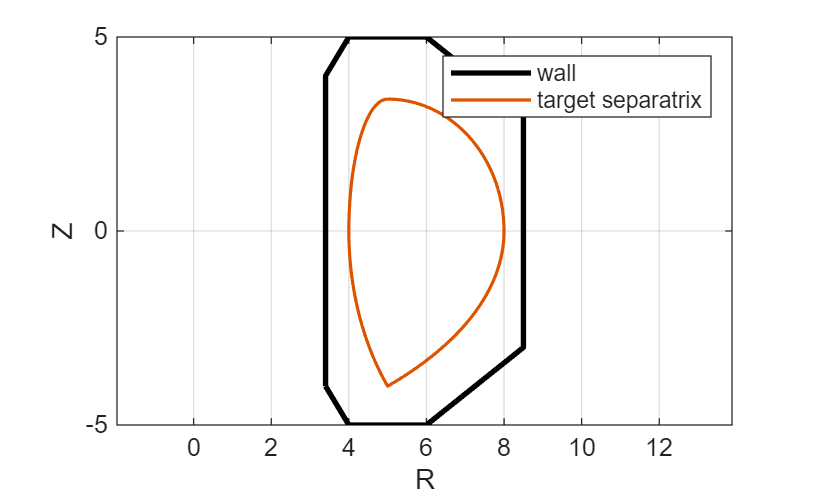

% show uploaded geometry and target separatrix
figure(1)
clf
geo.plot_wall()
hold on
equi.plot_separatrix();
axis equal
legend("wall","target separatrix")

So, you can run the equilibrium solver

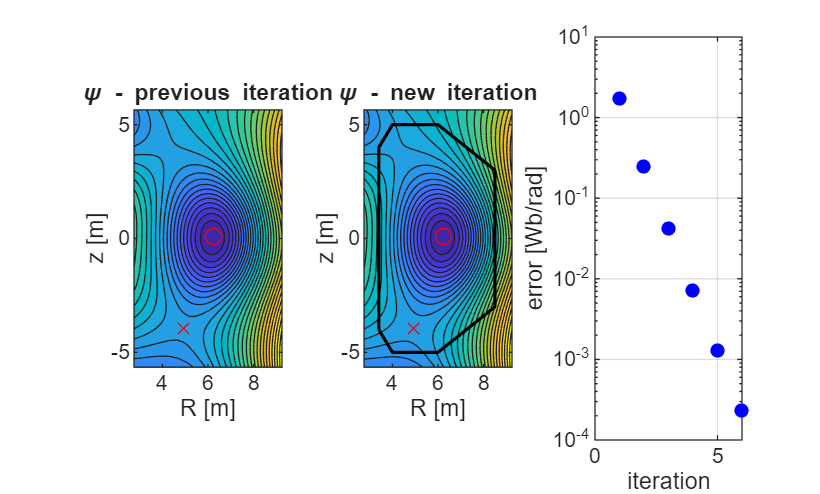

% solve equilibrium
equi = equi.solve_equilibrium();

and run the function to evaluate X-point, O-point, and LCFS

% post processing (Opoint, Xpoint, LFCS)
equi = equi.equi_pp();

Once you did that, you calculate the profiles

% mhd and kinetic profiles
equi  = equi.compute_profiles();

So, you have all the standard fields and you can decide to plot a specific quantity field. For example, in the following we plot both density and temperature

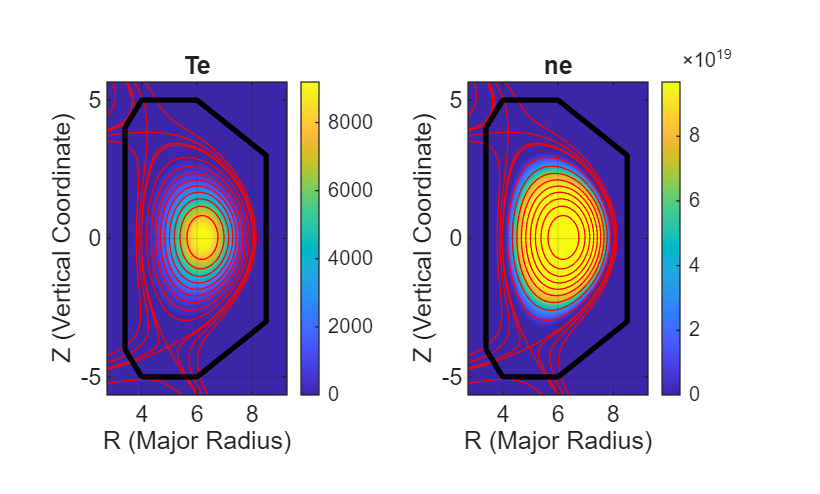

% plot my equilibrium and profiles
figure(2)
clf
subplot(1,2,1)
equi.plot_fields("Te",1)
hold on
equi.geo.plot_wall

subplot(1,2,2)
equi.plot_fields("ne",1)
hold on
equi.geo.plot_wall

**SynDiag** models synthetuc diagnostics given fields. SynDiag diagnostics are organised as it follows: 

- Initialise the diagnostic

- upload information (here, you can implement different configurations of the same diagnostics)

- measure (calculate values given equilibrium fields)

- plot

**Pick Up coils**

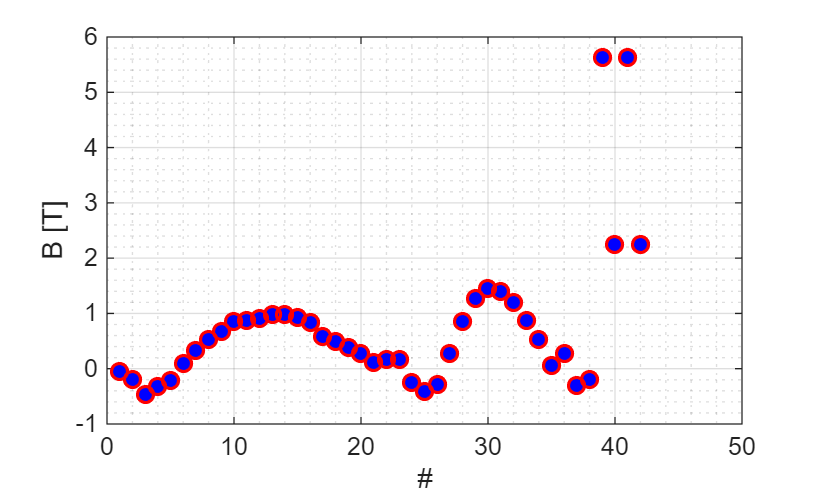

PickUp = Diag_PickUpCoils();
PickUp = PickUp.Upload(1);
PickUp = PickUp.measure(equi);
figure(3); clf; PickUp.plot_StandAlone();

**Flux Loops**

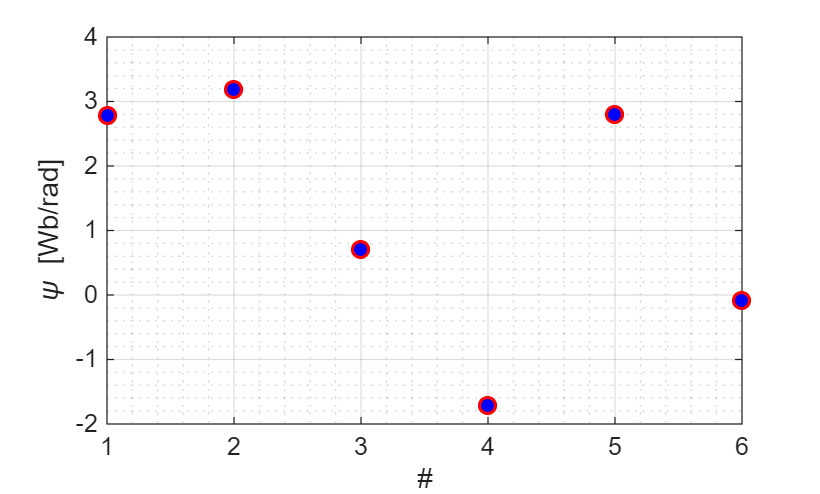

FluxLoops = Diag_FluxLoops();
FluxLoops = FluxLoops.Upload(1);
FluxLoops = FluxLoops.measure(equi);
figure(4); clf; FluxLoops.plot_StandAlone();

**Saddle Coils**

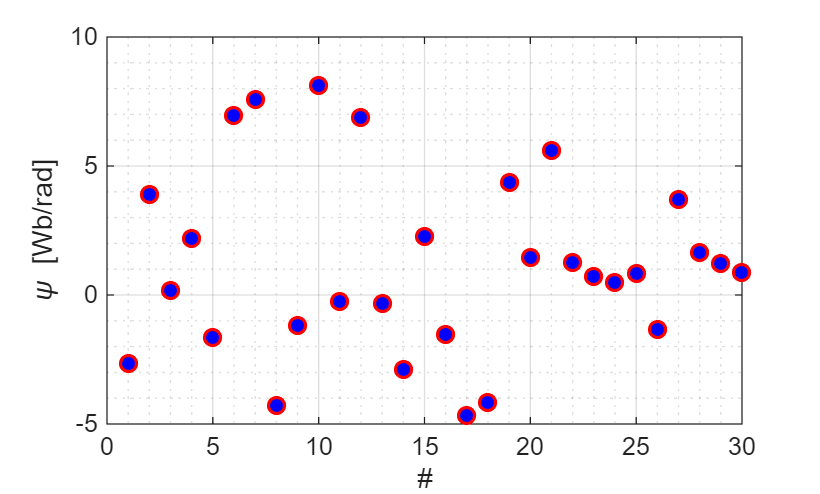

SaddleCoils = Diag_SaddleCoils();
SaddleCoils = SaddleCoils.Upload(1);
SaddleCoils = SaddleCoils.measure(equi);
figure(5); clf; SaddleCoils.plot_StandAlone();

**Thomson Scattering**

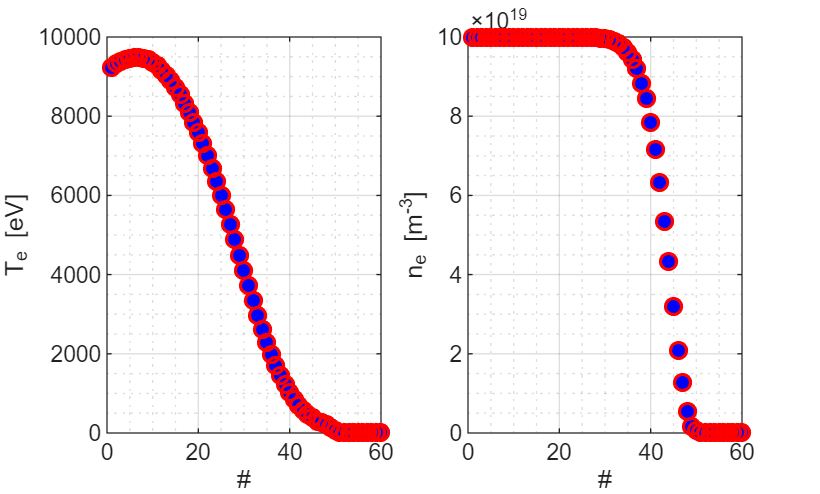

TS = Diag_ThomsonScattering();
TS = TS.Upload(1);
TS = TS.measure(equi);
figure(6); clf; TS.plot_StandAlone()

**Inteferometer-polarimeter**

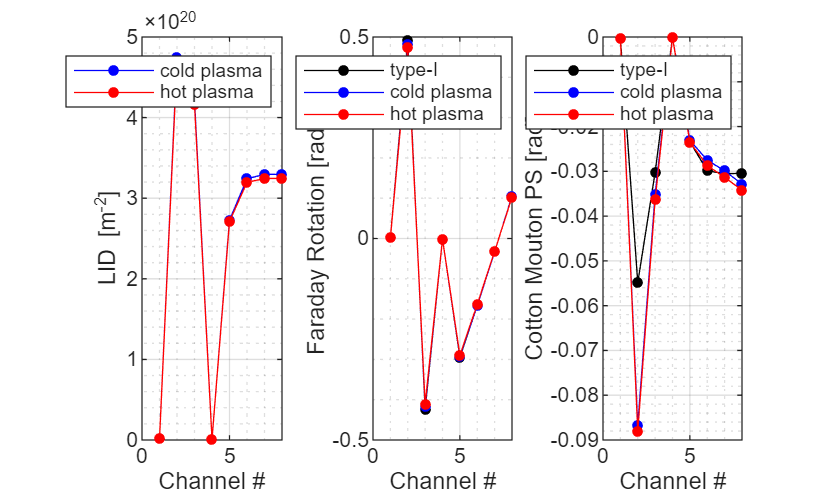

IntPol = Diag_InterferometerPolarimeter();
IntPol = IntPol.Upload(1);
IntPol = IntPol.measure(equi);
figure(7); clf; IntPol.plot_StandAlone;